% Experiment Number 2 - Solution of Transcendental Equation by False Position Method- Iteration Based Code
% Name of Programmer - Sahil Patra
% Roll No - 124MM0055

clc
clear all
f = @(x) x.*log10(x)-1.2

f = function_handle with value:
    @(x)x.*log10(x)-1.2


ni = input("\n Number of iterations ");
a= input("\nEnter First Guess ");
b= input("\nEnter Second Guess ");
while f(a)*f(b)>0
    fprintf(" The Guesses are incorrent");
    a = input("\nEnter a new First Guess ");
    b = input("\nEnter a new Second Guess ");  
end

for i = 1:ni
    c = a-(f(a)*((a-b)/(f(a)-f(b))));
    if f(a) * f(c) < 0 
        b = c;
    else 
        a = c;
    end
end

fprintf('The root is approximately: %.6f\n', c);

The root is approximately: 2.740646


error = abs(f(c));
fprintf("The Error in Calculation after %d iteration = %.6f",ni,error);

The Error in Calculation after 100 iteration = 0.000000

x1=linspace(-10,10,100);
y= f(x1);
plot(x1, y,"r",LineWidth=2);

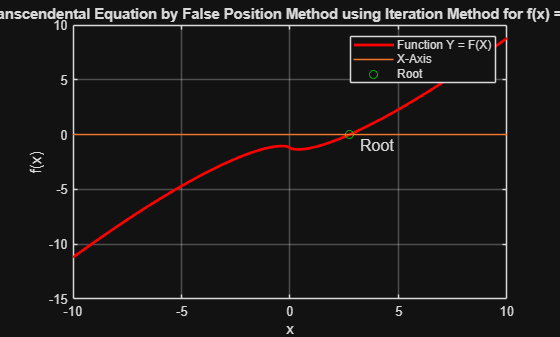

xlabel('x');
ylabel('f(x)');
title('Solution of Transcendental Equation by False Position Method using Iteration Method for f(x) = x * log10(x) - 1.2');
grid on;
hold on 
y1(1:ni)= 0;
plot(x1,y1);
plot(c, f(c), 'go');
text (c+0.5,f(c)-1,"Root",FontSize=12)
legend("Function Y = F(X)","X-Axis","Root")